Nx = 30;
error = "saw";
rng(123)

x = linspace(0, 2*pi, Nx+1);
x = x(1:end-1);

f_true = x.^.3.*sin(x);
if error == "saw"
    eps = (-1).^(1:Nx);
elseif error == "random"
    eps = randn(1, Nx);
end
f = f_true + eps;

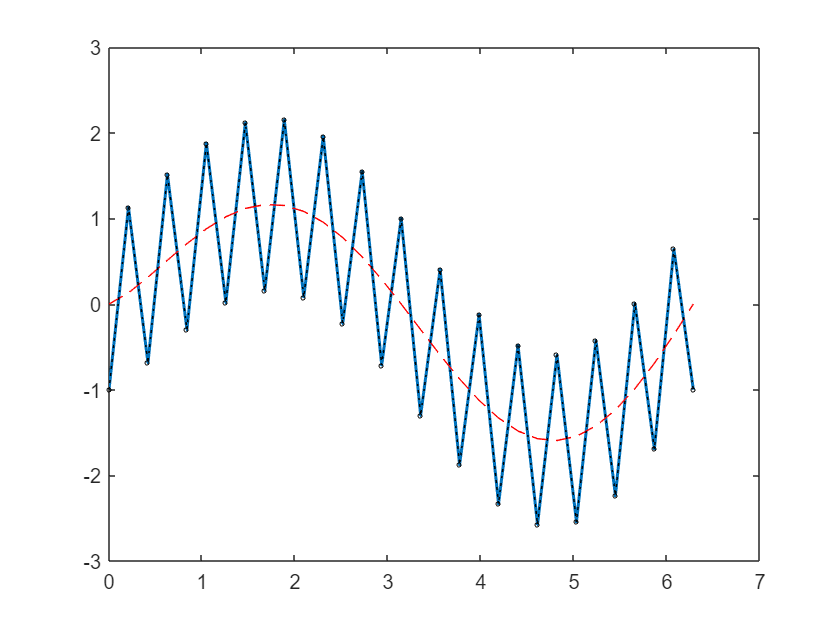

a = 1.5;
b = 2-a;
c = 1;

F = a*eye(Nx) + b/2*(diag(ones(Nx-1, 1), 1) + diag(ones(Nx-1, 1), -1));
G = eye(Nx) + c/2*(diag(ones(Nx-1, 1), 1) + diag(ones(Nx-1, 1), -1));

g = F\G * f.';

figure
plot([x, 2*pi], [g; g(1)], LineWidth = 1.5);
hold on;
plot([x, 2*pi], [f_true, f_true(1)], '--r', LineWidth = .2)
plot([x, 2*pi], [f, f(1)], ':ok', MarkerSize = 2)
hold off;